从TIFF中截取一段展示细胞活动的视频

此函数已弃用，将在未来版本删除。请改用[CellTrialsVideo](matlab:doc UniExp.CellTrialsVideo)

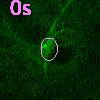

## 语法

## 输入参数

TiffPath(1,1)string，TIFF文件路径

### 名称值参数

名称值参数并非都是可选的。在某些条件下，某些参数可能是必需的。

#### C

(1,1)，要截取的通道，从0开始。对于多通道TIFF，必须指定此参数。

#### Z

(1,1)，要截取的Z层，从0开始。对于多Z层TIFF，必须指定此参数。

#### TSS

(1,1)struct，要截取的TIFF时段，必须包含以下字段：

- Start(1,1)，要截取的TIFF起始时点，从0开始

- Size(1,1)，要截取的TIFF时点长度

如果不指定此参数，将不作截取地输出TIFF全时段。

#### ROI

(2,2)table，要标注的细胞圈，必须包含名称为X、Y的两行，必须包含以下列：

- Center(2,1)，圆心坐标

- Radius(2,1)，半径

例如：

如果不指定此参数，将不标注细胞圈。

#### Window

(1,1)struct，要在图面上截取的XY观察窗。包含以下字段：

- Center(2,1)=ROI.Center，窗中心XY坐标。如果未指定ROI，此字段为必需。

- Size(1:2,1)=ROI.Radius*6。如果指定为标量，窗将是以Size为边长的正方形；否则将以Size的两个元素分别作为矩形窗的宽度和高度。如果未指定ROI，此字段为必需。

如果不指定此参数，将不作截取地输出完整图面。

#### ShowSeconds

(1,1)struct，要在视频中显示的计时读秒。包含以下字段：

- Range(1,2)，必需，秒数范围，两个元素分别是起始秒数和终止秒数。

- Size(1,1)=geomean(ROI.Radius)，字体大小。此值大致等于单行文本高度将会占据的像素数，但不同字体的渲染结果可能有所不同。如果未指定ROI，此字段为必需。

- Font(1,1)string="Microsoft YaHei"，渲染字体。可用listTrueTypeFonts查看所有可用的字体。

- Location(1,1)UniExp.Flags=UniExp.Flags.NorthWest，显示位置，可选：NorthWest，显示在左上角；NorthEast，显示在右上角；SouthWest，显示在左下角；SouthEast，显示在右下角。

计时读秒将仅显示整数秒数，并加后缀单位“s”，右对齐。如果不指定此参数，将不显示计时读秒。

#### Color

(1,3)，ROI和ShowSeconds标注所使用的RGB颜色，使用[0,1]范围内的single或[0,255]范围内的uint8值表示RGB分量。如果不指定此参数，将根据TIFF的通道颜色自动分配一个尽可能形成高对比的颜色。

#### OutputPath

(1,1)string，输出视频文件路径，建议使用mp4扩展名。无论扩展名为何，都将输出MPEG-4格式视频文件。如果不指定此参数，不会将视频输出到文件。

#### FrameRate

(1,1)，视频帧率FPS。如果指定了OutputPath，但未指定ShowSeconds，则此参数为必需。

## 返回值

Video(:,:,3,:)，生成的视频像素数组。第1维X，第2维Y，第3维RGB，第4维时间。注意维度顺序为XYCT，而MATLAB内置图像/视频处理函数的维度顺序通常为YXCT，使用pagetranspose在这两种维度顺序之间转换。

**See also** [listTrueTypeFonts](matlab:listTrueTypeFonts) [geomean](matlab:doc geomean) [VideoWriter](matlab:doc VideoWriter) [insertText](matlab:doc insertText) [pagetranspose](matlab:doc pagetranspose)

function Video=CellTrialVideo(TiffPath,options)
arguments
	TiffPath
	options.C
	options.Z
	options.TSS
	options.ROI
	options.Window
	options.ShowSeconds
	options.OutputPath
	options.FrameRate
	options.Color(1,3)
end
UniExp.Exception.Function_deprecated.Warn("CellTrialVideo已弃用，将在未来版本删除。请改用CellTrialsVideo");
Reader=Image5D.OmeTiffRWer.OpenRead(TiffPath);
C=Reader.SizeC>1;
import UniExp.Exception
if C
	if isfield(options,"C")
		C=options.C;
	else
		Exception.Parameter_C_must_be_specified_for_a_multichannel_TIFF.Throw;
	end
end
Z=Reader.SizeZ>1;
if Z
	if isfield(options,"Z")
		Z=options.Z;
	else
		Exception.Parameter_Z_must_be_specified_for_a_multi_Z_TIFF.Throw;
	end
end
if isfield(options,"TSS")
	TSS=options.TSS;
else
	TSS=struct(Start=0,Size=Reader.SizeT);
end
Video=rescale(permute(gpuArray(Reader.ReadPixels(TSS.Start,TSS.Size,Z,1,C,1)),[1,2,3,5,4]));
Color=Reader.ChannelColors(C+1);
Color=single([Color.R,Color.G,Color.B])/255;
Video=Video.*shiftdim(Color,-1);
if isfield(options,'Color')
	Color=options.Color;
	if isa(Color,'uint8')||any(Color>1)
		Color=single(Color)/255;
	end
else
	Color=GlobalOptimization.ColorAllocate(1,[Color;0,0,0]);
end
Color=shiftdim(Color,-1);
HasROI=isfield(options,'ROI');
VideoSize=single([Reader.SizeX;Reader.SizeY]);
if HasROI
	ROI=options.ROI;
	Xs=(1:VideoSize(1))';
	Ys=1:VideoSize(2);
	ROI.Radius=ROI.Radius+1;	
	Video=MATLAB.Ops.LogicalAssign(Video,edge(((Xs-ROI.Center("X"))/ROI.Radius("X")).^2+((Ys-ROI.Center("Y"))/ROI.Radius("Y")).^2>1),Color);
end
if isfield(options,'Window')
	Window=options.Window;
	if isfield(Window,'Center')
		Center=Window.Center;
	elseif HasROI
		Center=ROI.Center;
	else
		Exception.Window_Center_or_ROI_must_be_specified.Throw;
	end
	if isfield(Window,'Size')
		WindowSize=Window.Size;
		if any(WindowSize>VideoSize)
			Exception.Window_Size_larger_than_Tiff_size.Throw;
		end
	elseif HasROI
		WindowSize=min(ROI.Radius*6,VideoSize);
	else
		Exception.Window_Size_or_ROI_must_be_specified.Throw;
	end
	LeftTop=uint16(min(max(0,Center-WindowSize/2),VideoSize-WindowSize));
	Start=LeftTop+1;
	End=LeftTop+uint16(WindowSize);
	Video=Video(Start(1):End(1),Start(2):End(2),:,:);
	VideoSize=WindowSize;
end
import UniExp.Flags
HasShowSeconds=isfield(options,'ShowSeconds');
if HasShowSeconds
	ShowSeconds=options.ShowSeconds;
	Seconds=int8(floor(linspace(ShowSeconds.Range(1),ShowSeconds.Range(2),TSS.Size)));
	[Index,Seconds]=findgroups(Seconds);
	if isfield(ShowSeconds,'Size')
		TextSize=ShowSeconds.Size;
	elseif HasROI
		TextSize=geomean(ROI.Radius);
	else
		Exception.ShowSeconds_Size_or_ROI_must_be_specified.Throw;
	end
	if isfield(ShowSeconds,'Font')
		Var={ShowSeconds.Font};
	else
		Var={};
	end
	TextMasks=arrayfun(@(S)ComputerVision.TextMask(S,TextSize,Var{:}),compose("%is",Seconds),UniformOutput=false);
	TextMasks=pagetranspose(MATLAB.ElMat.PadCat(4,TextMasks{:},Padder=false,Alignment=[1,2,-2,0]));
	if isfield(ShowSeconds,'Location')
		Location=ShowSeconds.Location;
	else
		Location=Flags.NorthWest;
	end
	TextSize=size(TextMasks,1:2);
	switch Location
		case Flags.NorthWest
			Start=[0,0];
		case Flags.NorthEast
			Start=[VideoSize(1)-TextSize(1),0];
		case Flags.SouthWest
			Start=[0,VideoSize(2)-TextSize(2),0];
		case Flags.SouthEast
			Start=VideoSize-TextSize;
		otherwise
			Exception.Invalid_ShowSeconds_Location.Throw;
	end
	Subs=arrayfun(@colon,Start+1,Start+TextSize,UniformOutput=false);
	Video(Subs{:},:,:)=MATLAB.Ops.LogicalAssign(Video(Subs{:},:,:),TextMasks(:,:,:,Index),Color);
end
if isfield(options,'OutputPath')
	Writer=VideoWriter(options.OutputPath,'MPEG-4');
	if isfield(options,'FrameRate')
		Writer.FrameRate=options.FrameRate;
	elseif HasShowSeconds
		Writer.FrameRate=TSS.Size/(ShowSeconds.Range(2)-ShowSeconds.Range(1));
	else
		Exception.Output_file_must_specify_FrameRate_or_ShowSeconds.Throw;
	end
	Writer.open;
	Writer.writeVideo(gather(pagetranspose(Video)));
end